clear all
global mdl
mdl="sputnik";

global J

% Задание моментов инерции
KR_params;

$$ans = \left(\begin{array}{ccc} 2.4167e+03 & 0 & 0\\ 0 & 2.2375e+03 & 0\\ 0 & 0 & 2.1792e+03 \end{array}\right)$$


% Начальные отклонения
delta_omega0=[0.3; -0.2; 0.1]

delta_omega0 =     0.3000
   -0.2000
    0.1000


omega0=[-3; 2; 4]

omega0 =     -3
     2
     4


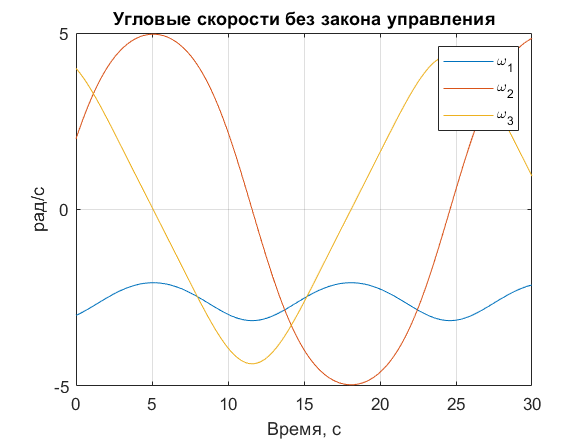

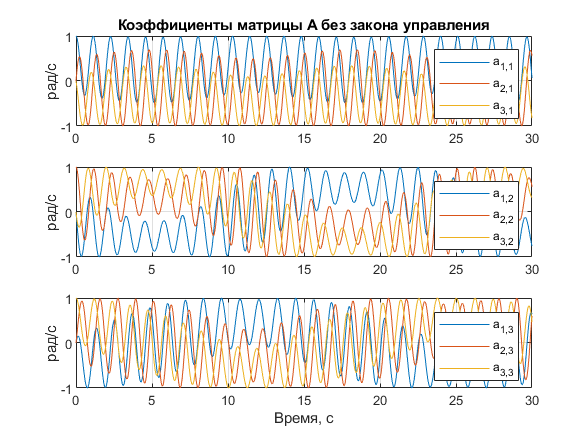


x0 = [omega0; reshape(eye(3),[9 1])];

% Уравнения Эйлера и Пуассона без управления
t=linspace(0,30,1e3);
[t,y]= ode45(@(t,x) eulPuassOrig(x(1:3),reshape(x(4:end),[3 3])),t,x0 );
eulPuassPlot(t,y,...
    "Угловые скорости без закона управления",...
    "Коэффициенты матрицы А без закона управления")

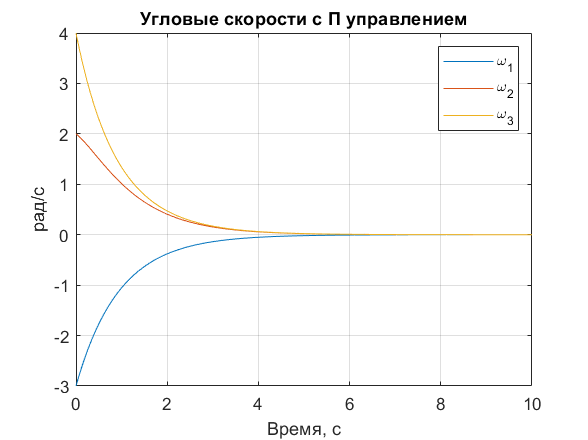

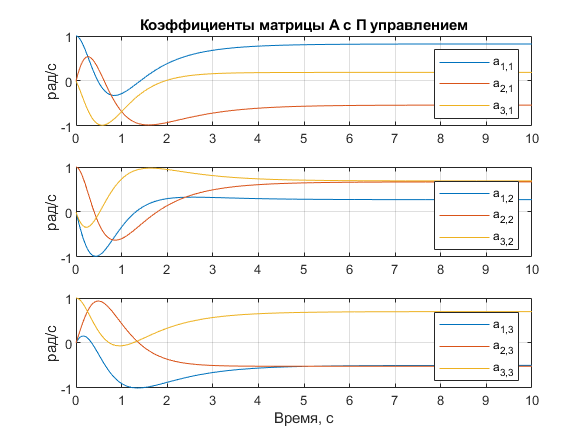


% Уравнения Эйлера и Пуассона с П управлением
t=linspace(0,10,1e3);
[t,y]= ode45(@(t,x) eulPuassPCtrl(x(1:3),reshape(x(4:end),[3 3])),t,x0 );
eulPuassPlot(t,y,...
    "Угловые скорости с П управлением",...
    "Коэффициенты матрицы А с П управлением")

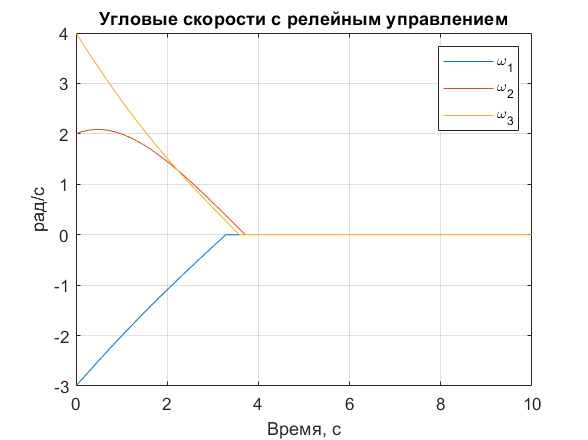

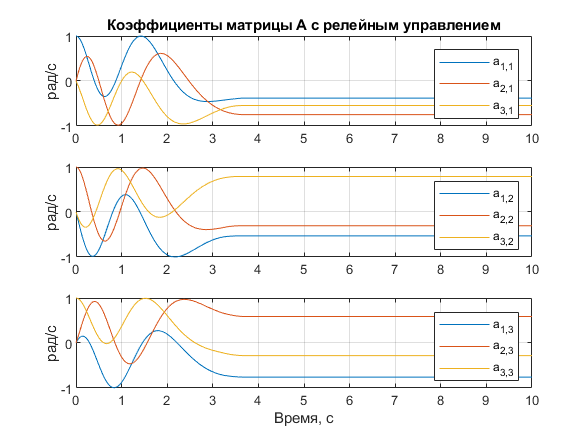


% Уравнения Эйлера и Пуассона с релейным управлением
t=linspace(0,10,1e3);
[t,y]= ode45(@(t,x) eulPuassRelayCtrl(x(1:3),reshape(x(4:end),[3 3])),t,x0 );
eulPuassPlot(t,y,...
    "Угловые скорости с релейным управлением",...
    "Коэффициенты матрицы А с релейным управлением")

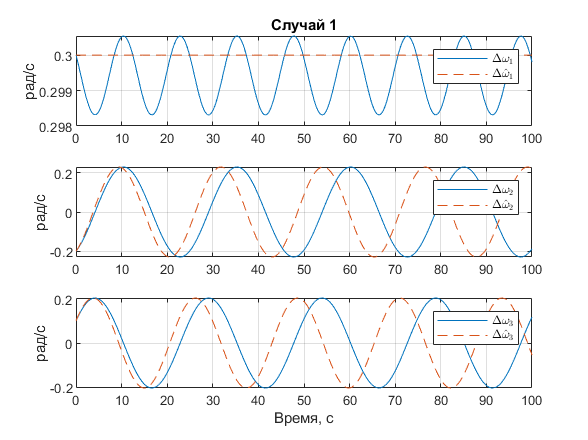

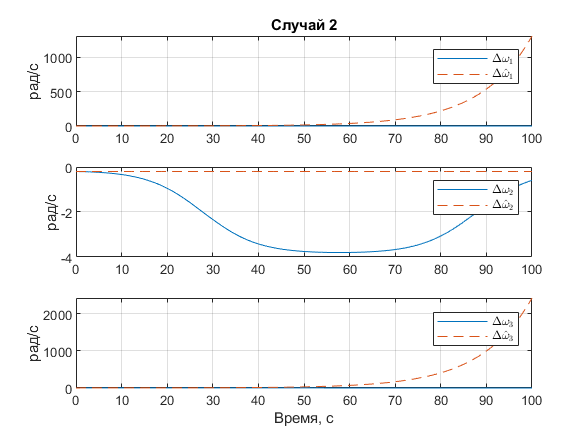

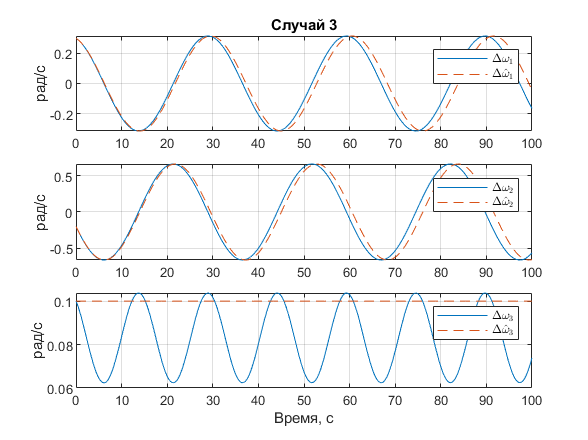


t=linspace(0,100,1e3);
for i=1:3
    % Уравнение Эйлера в отклонениях
    [~,y1]= ode45(@(t,x) eul_dev(x,omega0,i),t,  delta_omega0);
    % Уравнение Эйлера в первом приближении
    [~,y2]= ode45(@(t,x) eul_approx(x,omega0,i),t,  delta_omega0);

    figure
    tiledlayout(3,1)
    ax =[];
    for g = 1:3
        ax = [ax nexttile];
        plot(t,y1(:,g))
        hold on
        plot(t,y2(:,g),'--')
        grid on
        l1=sprintf("$\\Delta\\omega_%d$",g);
        l2=sprintf("$\\Delta\\hat\\omega_%d$",g);
        legend(l1,l2, "Interpreter","latex")
        ylabel("рад/с")
    end
    title(ax(1), "Случай "+ string(i))
    %linkaxes([ax(1) ax(2) ax(3)],'xy')
    xlabel("Время, с")

    %     figure
    %     plot(t,sum((y1.^2)*J,2)/2)
    %     hold on
    %     plot(t,sum((y2.^2)*J,2)/2)
    %     grid on
end

syms K [3,1]
syms omega [3,1]
-diag(K) * omega

$$ans = \left(\begin{array}{c} -K_{1}\,\omega_{1}\\ -K_{2}\,\omega_{2}\\ -K_{3}\,\omega_{3} \end{array}\right)$$

#### Строит графики для уравнений Эйлера и Пуассона

function eulPuassPlot(t,y,title1,title2)
w_orig=y(:,1:3);
col1=y(:,3+(1:3:9));
col2=y(:,3+(2:3:9));
col3=y(:,3+(3:3:9));

% Графики для Эйлера
figure
plot(t,w_orig)
grid on
legend("\omega_1","\omega_2","\omega_3")
degPerSecLabel()
title(title1)

% Графики для Пуассона
figure
tiledlayout(3,1)
ax1 = nexttile;
plot(t,col1)
grid on
legend("a_{1,1}","a_{2,1}","a_{3,1}")
ylabel("рад/с")


ax2 = nexttile;
plot(t,col2)
grid on
legend("a_{1,2}","a_{2,2}","a_{3,2}")
ylabel("рад/с")

ax3 = nexttile;
plot(t,col3)
grid on
legend("a_{1,3}","a_{2,3}","a_{3,3}")
ylabel("рад/с")

linkaxes([ax1 ax2 ax3],'xy')
xlabel("Время, с")
title(ax1,title2)
end

#### Подписи для вращения в градусах/c

function degPerSecLabel()
xlabel("Время, с")
ylabel("рад/с")
end

#### Уравнение Пуассона

function dA=puasson(omega,A)
Omega = [
    0 -omega(3) omega(2)
    omega(3) 0 -omega(1)
    -omega(2) omega(1) 0
    ];
dA= -Omega*A;
end

#### Уравнение Эйлера

function y=eul_orig(omega)
global J
y=inv(J) * (-cross(omega,J*omega));
end

#### Уравнения Эйлера и Пуассона без управления

function y = eulPuassOrig(omega,A)
dw = eul_orig(omega);
dA = puasson(omega,A);

y=[dw; reshape(dA,[9 1])];
end

#### Уравнения Эйлера и Пуассона с П регулятором

function y = eulPuassPCtrl(omega,A)
Kw=[1; 1; 1];
dw = eul_orig(omega) - Kw.*omega;
dA = puasson(omega,A);

y=[dw; reshape(dA,[9 1])];
end

#### Уравнения Эйлера и Пуассона с релейным регулятором

function y = eulPuassRelayCtrl(omega,A)
global J
M0=2000;
M = -M0.*sign(omega);

dw=inv(J) * (M-cross(omega,J*omega));
dA = puasson(omega,A);

y=[dw; reshape(dA,[9 1])];
end

#### Уравнение Эйлера в отклонениях

function y=eul_dev(deltaOmega, omega0, axisNum)
axisEnable=[0;0;0];
axisEnable(axisNum)=1;

deltaOmega=deltaOmega+omega0.*axisEnable;
y=eul_orig(deltaOmega);
end

#### Уравнение Эйлера в первом приближении

function y=eul_approx(deltaOmega, omega0, axisNum)

deltaOmega(axisNum) = omega0(axisNum);
y=eul_orig(deltaOmega);

y(axisNum)=0;
end